# Population

Elaborated by Natanael Bolson

Supervised by Prof. Tad Patzek and Maxim Yutkin

EGG-ANPERC-KAUST 06/2021

Description: Plot figures based on cumulative population, area and GDP

clc
clear
close all
Print='F';% T prints

## Load Data

load ../Data/Data_EIA_H.mat
load ../Data/Area_Country.mat

## Variables

Pop=Data_EIA_H.Population(:,end); 
Area=AreaCountry.totalAreaInSquareKilometres(1:end); %[km2]
GDP_cap=Data_EIA_H.GDP_cap(:,end);
GDP=GDP_cap.*Pop;
Labels=Data_EIA_H.Labels;
Tab=table(Area,Pop,GDP,GDP_cap);
Tab=[Labels,Tab];
Tab=rmmissing(Tab);

## Area

% Set limits
L=1e6;
S=1e5;
% Countries with area bigger than 1e6 km2
Large=find(Area>=L);
Large=setdiff(Large,1);
% Countries with area smaller than 1e5 km2
Small=find(Area<=S);
Medium=find(Area>S & Area<L);


## Population

P_S=(Pop(Small)');
P_M=(Pop(Medium)');
P_L=(Pop(Large)');

% Share of population in small size countries (%)
nansum(P_S)/Pop(1)*100

ans = 5.4659

% Share of population in medium size countries (%)
nansum(P_M)/Pop(1)*100

ans = 32.2783

% Share of population in large size countries (%)
nansum(P_L)/Pop(1)*100

ans = 62.2532

## Figures

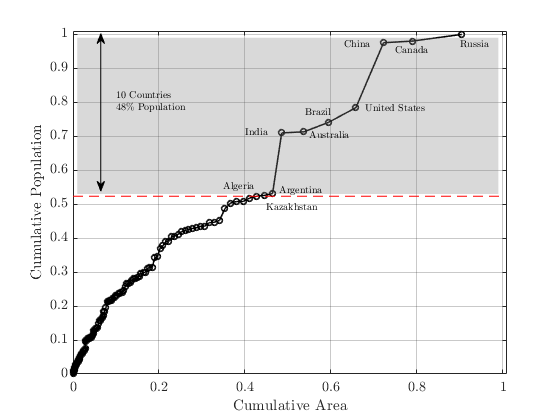

% Sorted Area X-Axis
Countries_Area={'Russia','Canada','China','United States','Brazil',...
'Australia','India','Argentina','Kazakhstan','Algeria'};
Tab=sortrows(Tab,"Area","ascend");
CA=cumsum(Tab.Area)/max(Area);
CP=cumsum(Tab.Pop)/max(Pop);

figure
plot(CA(1:end-1),CP(1:end-1),'o-k','LineWidth',1.5)

hold on
fill([0.01 0.01 0.99 0.99],[0.53 0.99 0.99 0.53],[0.5 0.5 0.5],...
    'FaceAlpha',0.3,'EdgeColor','none' )
grid on
ylim([0 1.01])
xlim([0 1.01])
xlabel('Cumulative~Area','Interpreter','latex')
ylabel('Cumulative~Population','Interpreter','latex')
text([0.9  0.75 0.63 0.68 0.54 0.55 0.4 0.48 0.45 0.35],...
     [0.97 0.95 0.97 0.78 0.77 0.7  0.71 0.54 0.49  0.55],Countries_Area,'Interpreter','latex')
annotation("doublearrow",[0.18 0.18],[0.545 0.92])
plot([0 1],[0.523548332176926 0.523548332176926],'--r')
text(0.1,0.8,{'10 Countries';'48\% Population'},'Interpreter','latex')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

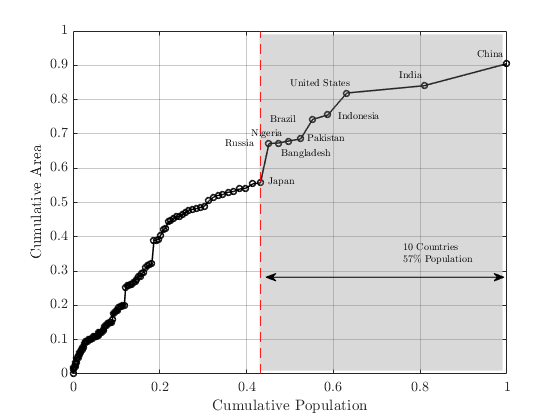

if Print=='T'
    print('-depsc2','-r400','Area_Cum.eps')
end


% Sorted Population X-Axis
Country_Pop={'China','India','United States','Indonesia','Brazil','Pakistan',...
'Nigeria','Bangladesh','Russia','Japan'};

Tab=sortrows(Tab,"Pop","ascend");
CA=cumsum(Tab.Area)/max(Area);
CP=cumsum(Tab.Pop)/max(Pop);

figure
plot(CP(1:end-1),CA(1:end-1),'o-k','LineWidth',1.5)
hold on
fill([0.43 0.99 0.99 0.43],[0.01 0.01 0.99 0.99],[0.5 0.5 0.5],'FaceAlpha',0.3,'EdgeColor','none' )
ylim([0 1.0])
text([0.93 0.75 0.5   0.61  0.455 0.54  0.41 0.48 0.35 0.45],...
     [0.93 0.87 0.845 0.75 0.74  0.685 0.70 0.64 0.67  0.56],Country_Pop,'Interpreter','latex')
ylabel('Cumulative~Area','Interpreter','latex')
xlabel('Cumulative~Population','Interpreter','latex')
grid on
annotation("doublearrow",[0.475 0.9],[0.34 0.34])
plot([0.431885795920658 0.431885795920658],[0 1],'--r')
text(0.76,0.35,{'10 Countries';'57\% Population'},'Interpreter','latex')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

if Print=='T'
    print('-depsc2','-r400','Pop_Cum.eps')
end

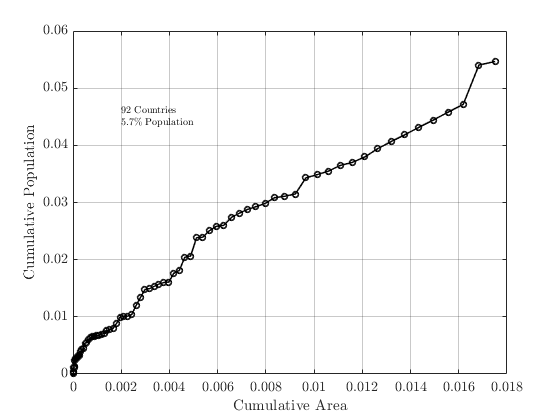

% Figure with cumulative population of small countries

Tab=sortrows(Tab,'Area',"ascend");
CAP=cumsum(Tab.Pop(1:92))/Pop(1);
CAS=cumsum(Tab.Area(1:92))/Area(1);

figure
plot(CAS,CAP,'o-k','LineWidth',1.5)
grid on
hold on
xlabel('Cumulative~Area','Interpreter','latex')
ylabel('Cumulative~Population','Interpreter','latex')
text(0.002,0.045,{'92 Countries';'5.7\% Population'},'Interpreter','latex')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

if Print=='T'
    print('-depsc2','-r400','Area_Out.eps')
end

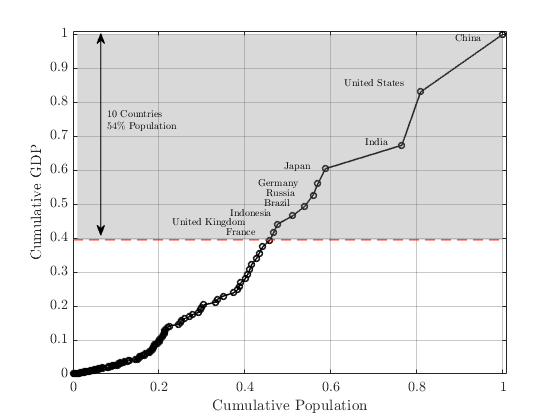

% Sorted total GDP 

Tab=sortrows(Tab,'GDP',"ascend");
CAP=cumsum(Tab.Pop(2:end))/Pop(1);
CGDP=cumsum(Tab.GDP(2:end))/GDP(1);
Country_GDP={'China','United States','India','Japan','Germany','Russia','Brazil',...
'Indonesia','United Kingdom','France'};

figure
plot(CAP(1:end-1),CGDP(1:end-1),'o-k','LineWidth',1.5)
grid on
hold on
fill([0.01 0.01 1 1],[0.395 1 1 0.395],[0.5 0.5 0.5],'FaceAlpha',0.3,'EdgeColor','none' )
ylim([0 1.01])
xlim([0 1.01])
text([0.89  0.63  0.68 0.49 0.43 0.45 0.445 0.365 0.23 0.355],...
     [0.985 0.855 0.68 0.61 0.56 0.53  0.50 0.47 0.445 0.415],Country_GDP,'Interpreter','latex')
plot([0 1],[0.395 0.395],'--r')
annotation("doublearrow",[0.18 0.18],[0.44 0.92])
ylabel('Cumulative~GDP','Interpreter','latex')
xlabel('Cumulative~Population','Interpreter','latex')
text(0.08,0.745,{'10 Countries';'54\% Population'},'Interpreter','latex')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

if Print=='T'
    print('-depsc2','-r400','Area_GDP.eps')
end

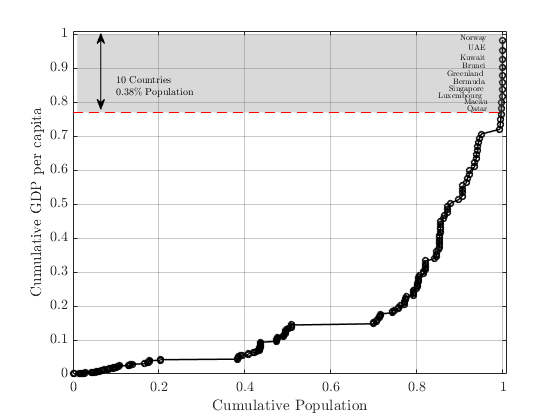

% Sorted GDP capita

Tab=sortrows(Tab,'GDP_cap',"ascend");
CAP=cumsum(Tab.Pop([1:112 114:end]))/Pop(1);
CGDP=cumsum(Tab.GDP_cap([1:112 114:end]))/nansum(GDP_cap);
Country_GDP={'Norway','UAE','Kuwait','Brunei','Greenland','Bermuda',...
'Singapore','Luxembourg','Macau','Qatar'};
figure
plot(CAP,CGDP,'o-k','LineWidth',1.5)
xlim([0 1.01])
ylim([0 1.01])
grid on
hold on
fill([0.01 0.01 1 1],[0.77 1 1 0.77],[0.5 0.5 0.5],'FaceAlpha',0.3,'EdgeColor','none' )
text([0.91 0.93 0.91 0.915 0.88 0.895 0.885 0.86 0.92 0.9275]-0.01,...
     [0.99 0.96 0.93 0.9075 0.8825 0.86   0.84  0.82 0.8 0.78],Country_GDP,...
     "HorizontalAlignment","left",'Interpreter','latex',"FontSize",8)
plot([0 1],[0.77 0.77],'--r')
annotation("doublearrow",[0.18 0.18],[0.74 0.92])
ylabel('Cumulative~GDP~per~capita','Interpreter','latex')
xlabel('Cumulative~Population','Interpreter','latex')
text(0.1,0.845,{'10 Countries';'0.38\% Population'},'Interpreter','latex')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.25,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

if Print=='T'
    print('-depsc2','-r400','Area_GDPcap.eps')
end